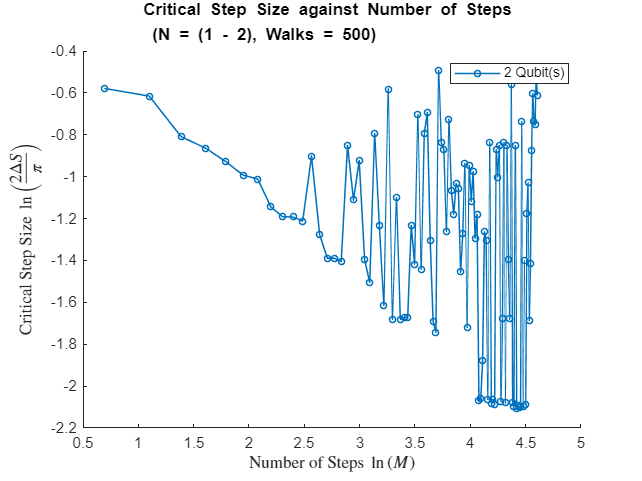

Number_of_Qubits =  2;
Number_of_Walks = 5e2;
Number_of_Steps = 100; 

Step_Size_Resolution = 2.5e-1;

%Test1 = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution);

Test2 = Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution);

function FP = Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution)

    FP = zeros(Number_of_Qubits-1, 2);
    
    Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution);
    Critical_Step_Sizes = interp1(Data(2,:),Data(1,:),Precision);
    
    figure;
    hold on;
    for j = 1:(Number_of_Qubits-1)
    
        
    
        plot(log(1:Number_of_Steps), log((2/pi)*Critical_Step_Sizes(j, :)), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubits', j+1));
        
        xlabel('Number of Steps $ \ln \left( M \right) $', 'Interpreter', 'latex');
        xlim([log(3),log(Number_of_Steps)]);
        ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
        title(sprintf('Critical Step Size against Number of Steps \\newline (N = (2 - %d), Walks = %d)', Number_of_Qubits, Number_of_Walks));
        legend;
    
        
    
    end
    hold off;
    drawnow;
    
    B = zeros(Number_of_Qubits, 1);
    A = zeros(Number_of_Qubits, 1);
    
    for j = 1:(Number_of_Qubits-1)
    
        Data_Set = Critical_Step_Sizes(j, :);
        FP = polyfit(log(1:Number_of_Steps), log(Data_Set), 1);
        
        B(j) = FP(1);
        A(j) = exp(FP(2));
        
        fprintf('%d Qubits: B(N) = %f, A(N) = %f\n', j+1, -B(j), A(j));
    end  
    
    figure;
    scatter(2:Number_of_Qubits, A(:,1), 'DisplayName', 'A Values');
    legend;
    xlabel('Number of Qubits');
    title('A Values from Fitting');
    
    figure;
    scatter(2:Number_of_Qubits, B(:,1), 'DisplayName', 'B Values');
    legend;
    xlabel('Number of Qubits');
    title('B Values from Fitting');

end


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution)

figure;
hold on;

Critical_Step_Size = zeros(Number_of_Qubits,Number_of_Steps);
Data = zeros(2,length(0:Step_Size_Resolution:1));

for N = 2:Number_of_Qubits

    Precision = pi*0.5 - acos(1/sqrt(2^N));

    for M = 1:Number_of_Steps

        j=1;
        
        for S = 0:Step_Size_Resolution:1
            
            Data(1,j) = S;
            Data(2,j) = Random_Walk_Algorithm(N, M, Number_of_Walks, S);
        
            j=j+1;
        end   
    end
end

end

function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)

    Final_Distances = zeros(1,Number_of_Walks);

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
    Vector_Database= randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    
    for i = 1:Number_of_Walks
     
            Vector = Pole_Vector; 
        
                    for j = 1:Number_of_Steps

                        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);

                        Orthogonal_Vector = Selected_Vector - dot(Vector,Selected_Vector)*Vector;

                        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

                        Vector = (cos(Step_Size) * Vector) + (sin(Step_Size) * Normalized_Vector);

                    end 

              Final_Distances(:,i) = Fubini_Study_Distance(Pole_Vector, Vector);
    end 

    RWA = pi*0.5 - mean(Final_Distances);
end 

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end